Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 9 -- Engine Data

%{
    This will be a script that will be used to complete Assignment9 
    for ME 5714 -- Digital Signal Processing.

    Sam Kramer
    April 3rd, 2023
%}

% --Setup
clear; clc; close all; format compact;

Assignment 9

Turbine Analysis

Given the turbine data in the file turbine .mat, estimate the autospectrum of the pressure probe using 10 vectors of 8096. 

From the spectral data, find the number of blades on the turbine inlet stage. 

You can find the rotational speed from the key phasor data. Sample rate 128K samples /sec. 

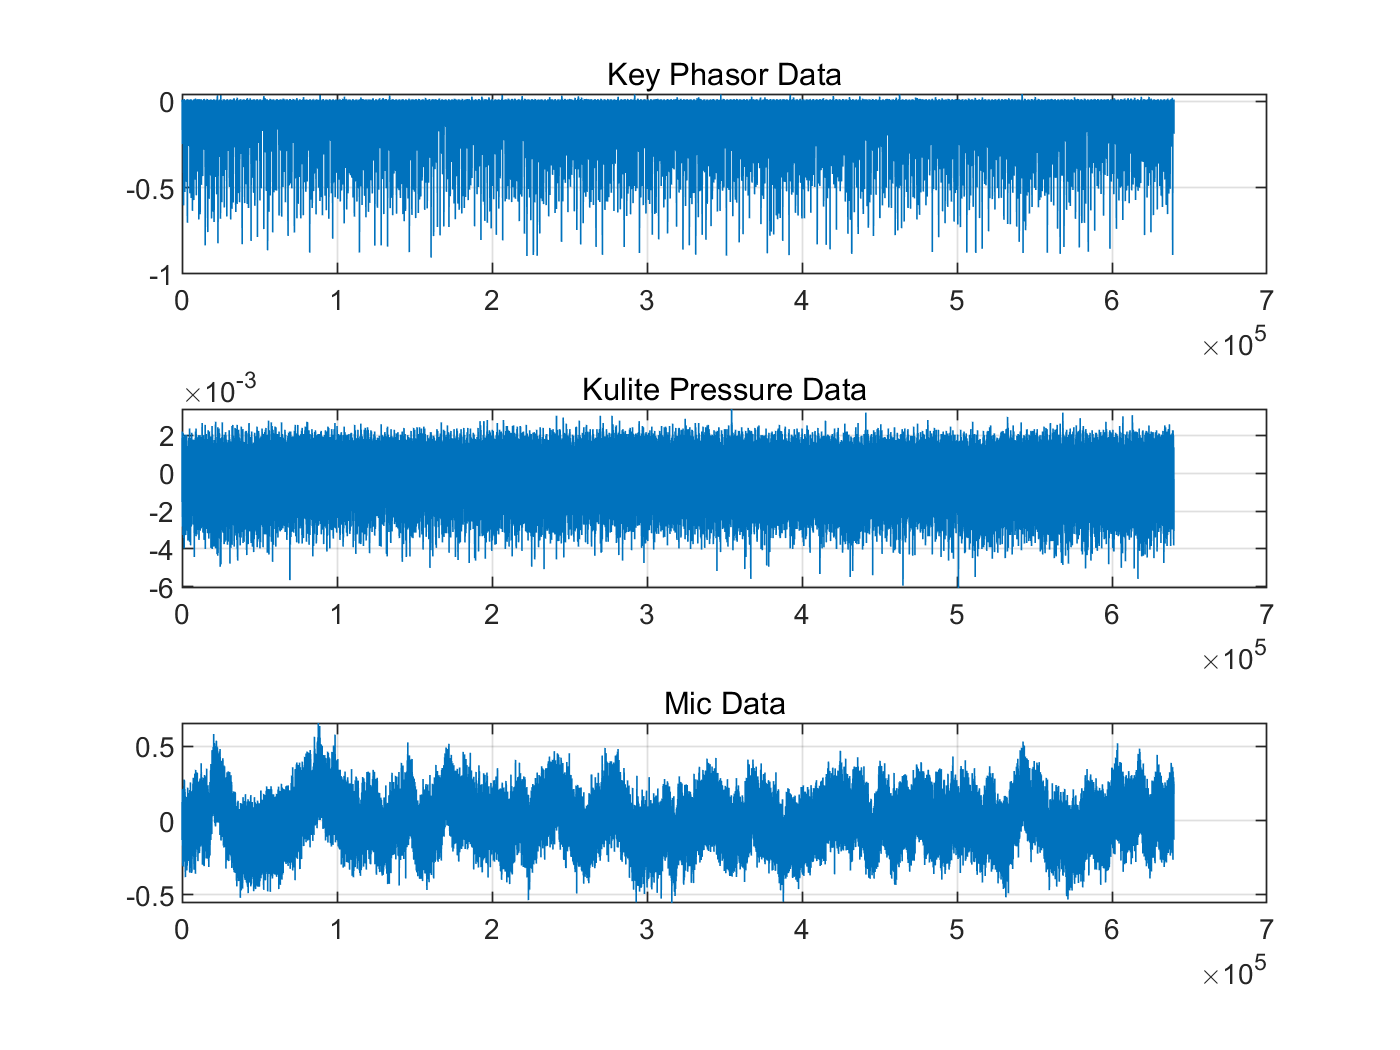

% --Load in data
    data = load('turbine data-1.mat');
    key_phasor = data.keyphasor;
    kulite_pressure = data.kulitepressure;
    mic_data = data.mic;
    
% --Zero Mean Data
    key_phasor = key_phasor - mean(key_phasor);
    kulite_pressure = kulite_pressure - mean(kulite_pressure);
    mic_data = mic_data - mean(mic_data);
    
% --Plot Data
    figure(1)
    subplot(3,1,1)
    plot(key_phasor)
        hold on
        grid on
        subtitle('Key Phasor Data')
    
    subplot(3,1,2)
    plot(kulite_pressure)
        grid on
        subtitle('Kulite Pressure Data')
    
    subplot(3,1,3)
    plot(mic_data)
        grid on
        subtitle('Mic Data')

## Finding Autospectrum of Pressure Data

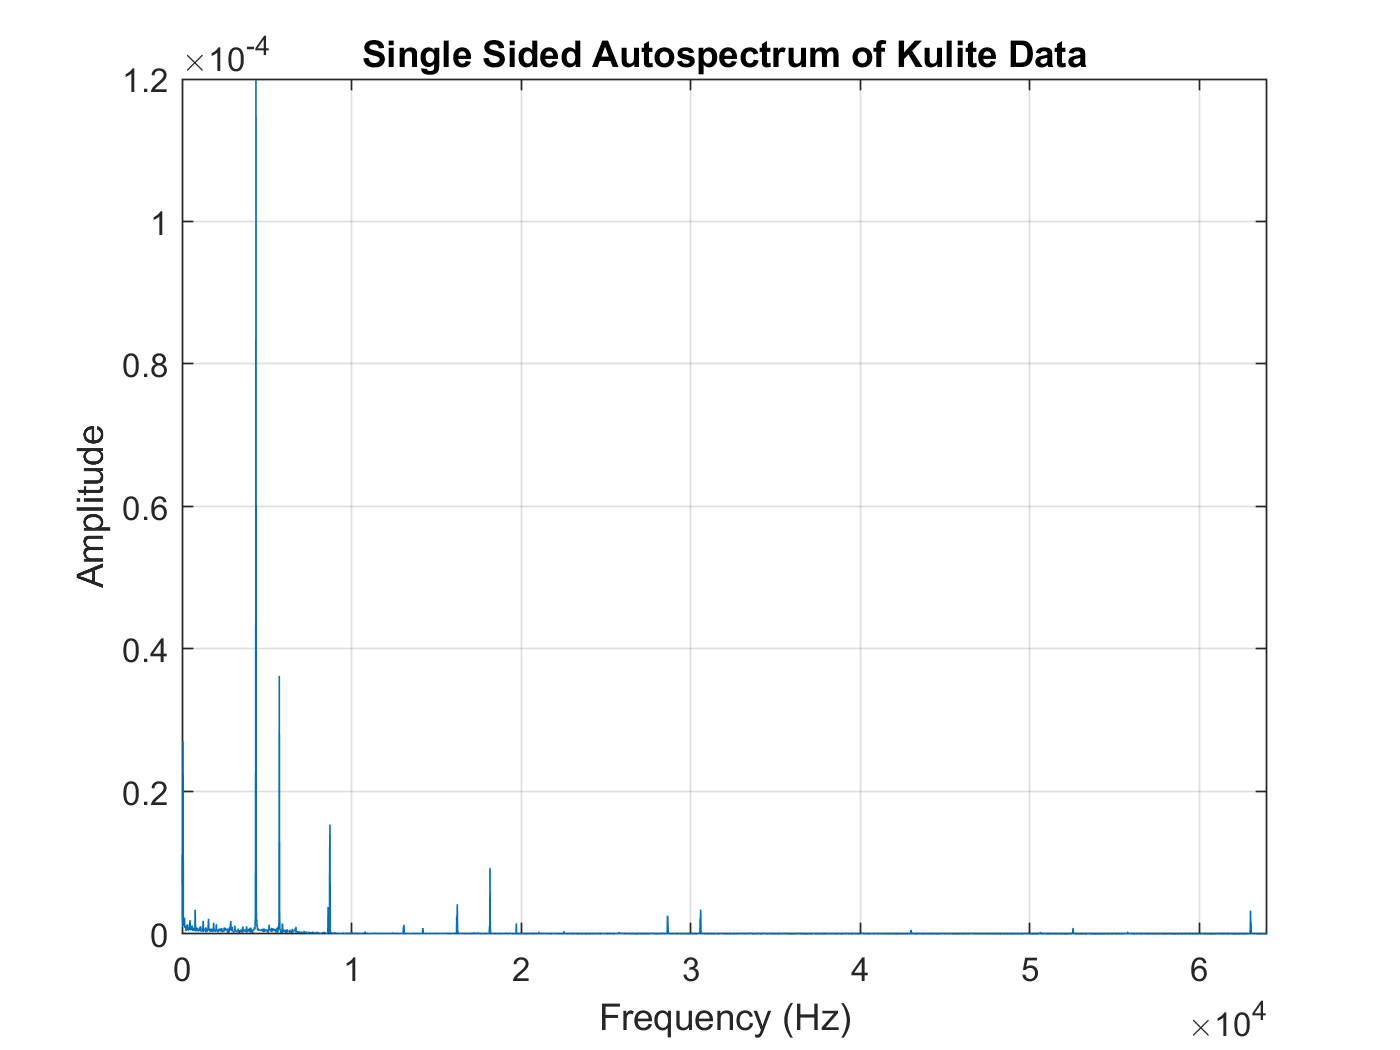

% --Making 10 vectors
    vector_numbers = 10;
    kulite_data = [];
    data_points = 8096;         % Target Number of data points
    sample_freq = 128000;       % Sample Frequency (samples/sec)
    
    for N = 1:vector_numbers
        
        kulite_data = [kulite_data, kulite_pressure(N*8096:(N+1)*8096 - 1, 1)];
        
    end
    
% --Taking autospectrum 
    auto_spect = autospec(kulite_data);
    
% --Selecting Frequency
    T = data_points/sample_freq;
    frequency = (1/T)*(0:(data_points - 1));
    
% --Plot autospectrum data
    figure(2)
    plot(frequency, auto_spect)
        grid on
        hold on
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        title('Single Sided Autospectrum of Kulite Data')
        xlim([0 max(frequency)/2])

## Finding the Rotational Rate of the Turbine

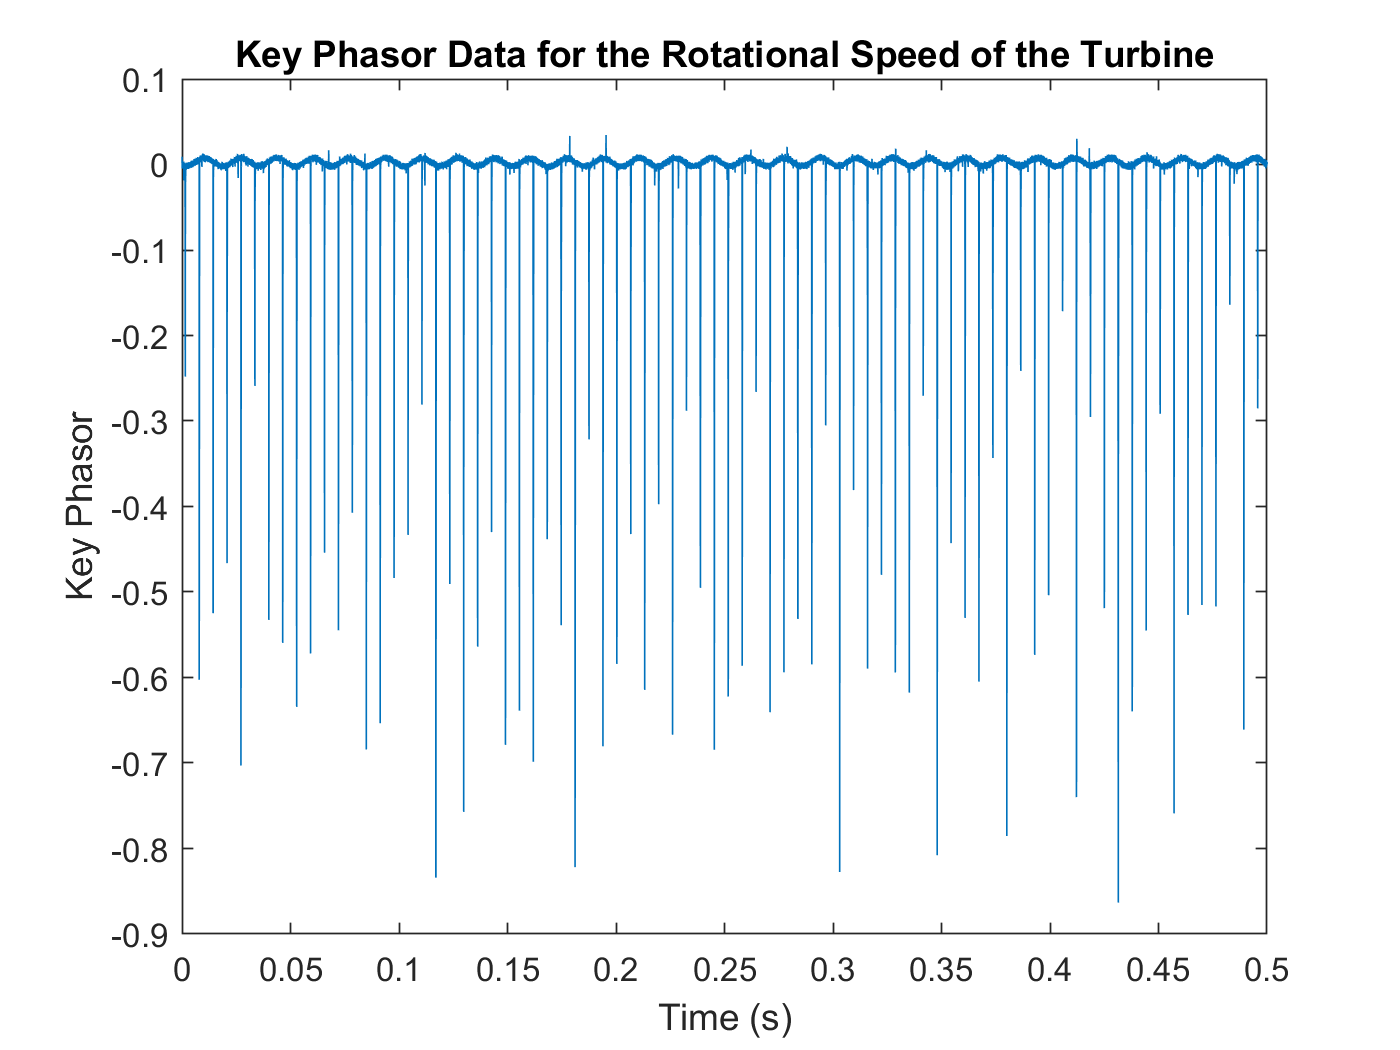

% --Zooming in on key phasor plot
    time = (0:length(key_phasor) - 1)*(1/sample_freq);
    figure(3)
    plot(time, key_phasor)
        xlim([0 0.5])
        xlabel('Time (s)')
        ylabel('Key Phasor')
        title('Key Phasor Data for the Rotational Speed of the Turbine')

        
% --Finding time difference
    time_diff = 0.01434 - 0.0079;
    freq = 1/time_diff;
    rotational_speed = freq*60;
    
    fprintf('The rotational rate is %3.3f RPM and %3.3f Hz \n',rotational_speed,freq)

The rotational rate is 9316.770 RPM and 155.280 Hz 


## Finding Number of Blades

% --Finding frequency of the pressure data
    [maxval, index] = max(auto_spect);
    turbine_speed = frequency(index);
    num_blades = turbine_speed/freq;
    
    fprintf('The number of blades that the turbine has is %3.3f',num_blades)

The number of blades that the turbine has is 28.102

## Functions

function auto_spect = autospec(data)

    % --Setup
        auto_spect = zeros(length(data),1);
    
    % --Compute autospectrum of data
        for i = 1:width(data)
        
            % --Take FFT of Column data
                fftdata = fft(data(:,i));
            
            % --Find autospectrum and add it to previous value
                auto = fftdata .* conj(fftdata);
                auto = auto * 2 / (length(data)*width(data));
                auto_spect = auto_spect + auto;
        
        end
        
    % --Normalize
        auto_spect = auto_spect/ (width(data));
        
end